# **KINOVA Gen3 Manipulator Path Planning using STOMP**

This example shows how to plan a collision-free robot path from an initial to a desired end-effector pose using STOMP ([Stochastic trajectory optimization for motion planning](https://ieeexplore.ieee.org/document/5980280))[1].

## Robot Description and Poses

Load the KINOVA Gen3 rigid body tree (RBT) model.

robot_name = 'universalUR5';
robot = loadrobot(robot_name, 'DataFormat', 'column'); % Note there are different data formats for loading the robot (chosen in the 2nd argument)

Get the number of joints.

numJoints = numel(homeConfiguration(robot));

Specify the robot frame where the end-effector is attached.

endEffector = "tool0"; 

Specify initial and desired end-effector poses. Use inverse kinematics to solve for the initial robot configuration given a desired pose.

% Initial end-effector pose
taskInit = trvec2tform([[-0.0 0.0 1.0]])*axang2tform([0 1 0 pi]);

% Compute current robot joint configuration using inverse kinematics
ik = inverseKinematics('RigidBodyTree', robot);
ik.SolverParameters.AllowRandomRestart = false;
weights = [1 1 1 1 1 1];

currentRobotJConfig = ik(endEffector, taskInit, weights, robot.homeConfiguration);

% The IK solver respects joint limits, but for those joints with infinite
% range, they must be wrapped to a finite range on the interval [-pi, pi].
% Since the the other joints are already bounded within this range, it is
% sufficient to simply call wrapToPi on the entire robot configuration
% rather than only on the joints with infinite range.
currentRobotJConfig = wrapToPi(currentRobotJConfig);

% Final (desired) end-effector pose
taskFinal = trvec2tform([0.2 0.2 0.35])*axang2tform([0 1 0 pi]);  
anglesFinal = rotm2eul(taskFinal(1:3,1:3),'XYZ');
poseFinal = [taskFinal(1:3,4);anglesFinal']; % 6x1 vector for final pose: [x, y, z, phi, theta, psi]

% Final configuration
finalRobotJConfig = ik(endEffector, taskFinal, weights, currentRobotJConfig);
finalRobotJConfig = wrapToPi(finalRobotJConfig);

## Collision Meshes and Obstacles

MATLAB has its own collision world functions to check for and avoid collisions (e.g., collisionSphere, collisionBox, etc). Here, we follow the STOMP paper to set up the voxel world and using the signed Euclidean distance function for this purpose, which is a common practice in robotics perception, mapping, and collision avoidance. We shall still use the MATLAB built-in collision object functions to visualize the object for the convenience. See more details in the following helper functions.

helperCreateObstaclesKINOVA;

Visualize the robot at the initial configuration. You should see the obstacles in the environment as well.

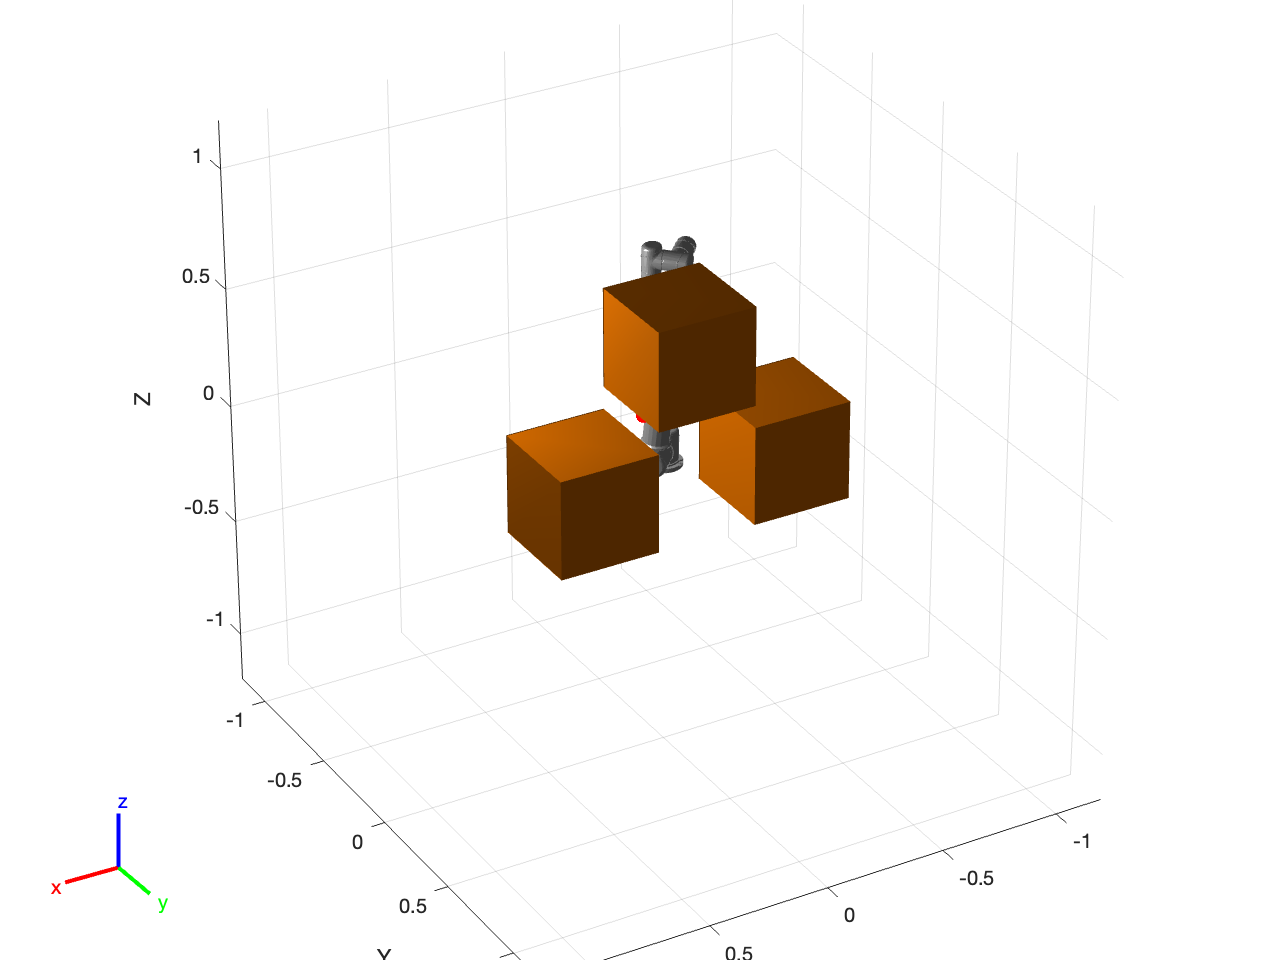

x0 = [currentRobotJConfig', zeros(1,numJoints)];
helperInitialVisualizerKINOVA;

Specify a safety distance away from the obstacles. This value is used in the inequality constraint function of the nonlinear MPC controller.

safetyDistance = 0.01; 

## Path Planning using STOMP

The following helper function contain the setup and execution of the STOMP algorithm for collision-avoidance planning.

Elapsed time is 5.125630 seconds.


Qtheta = 3.1440e+04

RAR = 9.8682

Elapsed time is 4.829595 seconds.


Qtheta = 3.0607e+04

RAR = 9.8656

Elapsed time is 4.912671 seconds.


Qtheta = 2.9144e+04

RAR = 9.8661

Elapsed time is 5.004104 seconds.


Qtheta = 2.8886e+04

RAR = 9.8591

Elapsed time is 4.980507 seconds.


Qtheta = 2.8394e+04

RAR = 9.8591

Elapsed time is 4.852797 seconds.


Qtheta = 2.8514e+04

RAR = 9.8556

Elapsed time is 4.689135 seconds.


Qtheta = 2.7528e+04

RAR = 9.8555

Elapsed time is 4.851989 seconds.


Qtheta = 2.7257e+04

RAR = 9.8503

Elapsed time is 4.802179 seconds.


Qtheta = 2.6984e+04

RAR = 9.8428

Elapsed time is 4.718598 seconds.


Qtheta = 2.7359e+04

RAR = 9.8435

Elapsed time is 4.760364 seconds.


Qtheta = 2.7210e+04

RAR = 9.8400

Elapsed time is 4.847480 seconds.


Qtheta = 2.7666e+04

RAR = 9.8386

Elapsed time is 4.660753 seconds.


Qtheta = 2.6937e+04

RAR = 9.8338

Elapsed time is 4.473161 seconds.


Qtheta = 2.7190e+04

RAR = 9.8286

Elapsed time is 4.520451 seconds.


Qtheta = 2.7224e+04

RAR = 9.8281

Elapsed time is 4.470067 seconds.


Qtheta = 2.7213e+04

RAR = 9.8267

Elapsed time is 4.471152 seconds.


Qtheta = 2.7432e+04

RAR = 9.8250

Elapsed time is 4.733505 seconds.


Qtheta = 2.7390e+04

RAR = 9.8177

Elapsed time is 4.812746 seconds.


Qtheta = 2.7416e+04

RAR = 9.8192

Elapsed time is 4.878691 seconds.


Qtheta = 2.7399e+04

RAR = 9.8184

Elapsed time is 4.746528 seconds.


Qtheta = 2.7291e+04

RAR = 9.8201

Elapsed time is 4.959734 seconds.


Qtheta = 2.7625e+04

RAR = 9.8220

Elapsed time is 4.915441 seconds.


Qtheta = 2.7686e+04

RAR = 9.8217

Elapsed time is 4.526899 seconds.


Qtheta = 2.7727e+04

RAR = 9.8175

Elapsed time is 4.674604 seconds.


Qtheta = 2.7418e+04

RAR = 9.8160

Elapsed time is 4.793055 seconds.


Qtheta = 2.7827e+04

RAR = 9.8092

Elapsed time is 4.960034 seconds.


Qtheta = 2.8404e+04

RAR = 9.8068

Elapsed time is 4.614208 seconds.


Qtheta = 2.8181e+04

RAR = 9.8042

Elapsed time is 4.534729 seconds.


Qtheta = 2.8131e+04

RAR = 9.8051

Elapsed time is 4.938158 seconds.


Qtheta = 2.7887e+04

RAR = 9.8042

Elapsed time is 4.564299 seconds.


Qtheta = 2.7600e+04

RAR = 9.8069

Elapsed time is 4.530329 seconds.


Qtheta = 2.7595e+04

RAR = 9.8054

Elapsed time is 4.668538 seconds.


Qtheta = 2.7435e+04

RAR = 9.8015

Elapsed time is 4.777807 seconds.


Qtheta = 2.7367e+04

RAR = 9.8069

Elapsed time is 4.611803 seconds.


Qtheta = 2.7260e+04

RAR = 9.8041

Elapsed time is 4.523646 seconds.


Qtheta = 2.7272e+04

RAR = 9.8026

Elapsed time is 4.588739 seconds.


Qtheta = 2.7266e+04

RAR = 9.8007

Elapsed time is 4.764384 seconds.


Qtheta = 2.7331e+04

RAR = 9.7991

Elapsed time is 4.821739 seconds.


Qtheta = 2.7260e+04

RAR = 9.7970

Elapsed time is 4.614672 seconds.


Qtheta = 2.7001e+04

RAR = 9.7946

Elapsed time is 4.798120 seconds.


Qtheta = 2.6954e+04

RAR = 9.7933

Elapsed time is 4.624793 seconds.


Qtheta = 2.7434e+04

RAR = 9.7919

Elapsed time is 4.491084 seconds.


Qtheta = 2.7008e+04

RAR = 9.7927

Elapsed time is 4.574320 seconds.


Qtheta = 2.6903e+04

RAR = 9.7881

Elapsed time is 4.964132 seconds.


Qtheta = 2.6804e+04

RAR = 9.7874

Elapsed time is 4.522032 seconds.


Qtheta = 2.6844e+04

RAR = 9.7854

Elapsed time is 4.609080 seconds.


Qtheta = 2.6747e+04

RAR = 9.7832

Elapsed time is 4.647997 seconds.


Qtheta = 2.6767e+04

RAR = 9.7784

Elapsed time is 4.644637 seconds.


Qtheta = 2.7166e+04

RAR = 9.7785

Elapsed time is 4.779112 seconds.


Qtheta = 2.7233e+04

RAR = 9.7781

Elapsed time is 4.730389 seconds.


Qtheta = 2.6896e+04

RAR = 9.7769

Maximum iteration (50) has reached.
STOMP Finished.


isTrajectoryInCollision = logical
   0


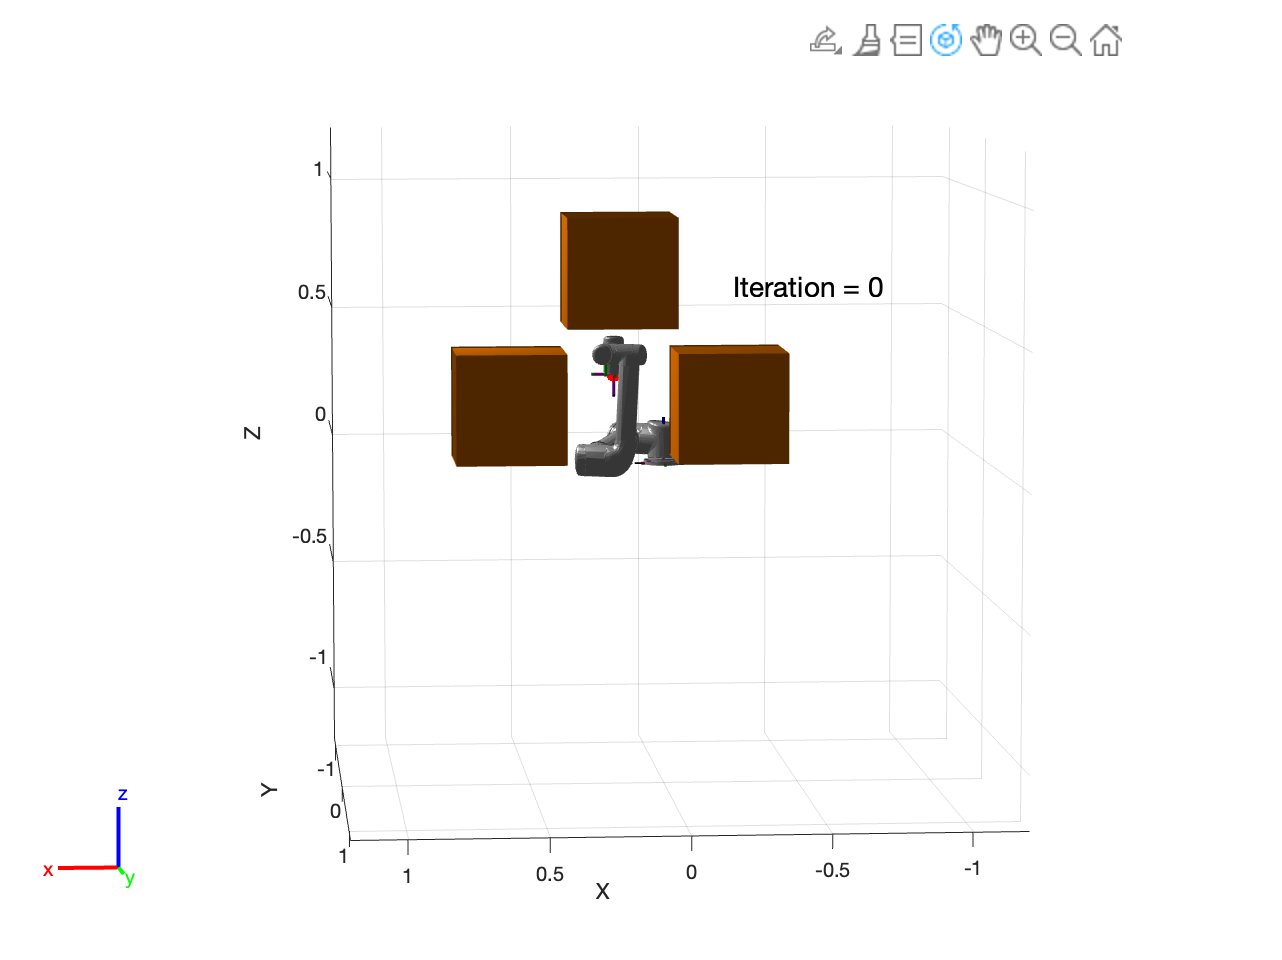

helperSTOMP;

[1] M. Kalakrishnan, S. Chitta, E. Theodorou, P. Pastor and S. Schaal, "STOMP: Stochastic trajectory optimization for motion planning," *2011 IEEE International Conference on Robotics and Automation*, 2011, pp. 4569-4574, doi: 10.1109/ICRA.2011.5980280.